# Distributed Coding Live Script - Single Neuron All Trials

## Setup

### MatNWB

Start by setting up your MATLAB workspace. The code below clones the MatNWB repo to the current directory and adds the folder ontaining the MatNWB package to the MATLAB search path. MatNWB works by automatically creating API classes based on a defined schema. Running the generateCore() function generates these classes for the lastest schema version.

!git clone https://github.com/NeurodataWithoutBorders/matnwb.git
cd ./matnwb
addpath(genpath(pwd));
generateCore();
cd ..

### distributed-coding-matnwb

You will also need the distributed-coding-matnwb repo, which has some useful plotting function

!git clone https://github.com/catalystneuro/distributed-coding-matnwb.git
cd ./distributed-coding-matnwb
addpath(genpath(pwd));
generateCore();
cd ..

### DANDIset

Download the relevant [DANDIset](https://dandiarchive.org/dandiset/000017/draft)

## Load in file

% path to file, change to desired file
DANDIset_folder = '~/DANDIsets/000017/';
filepath = [DANDIset_folder 'sub-Moniz/sub-Moniz_ses-20170515T120000.nwb'];
% read in file
nwb_file = nwbRead(filepath);
% fetch information about units
unit_info = getUnitInfo(nwb_file);
% display number units
nunits = length(unit_info);
fprintf('Total units: %d\n', nunits)

Total units: 606


## Select neuron and plot response

% recreate Figure 2a-c from Steinmetz, N. A., Zatka-Haas, P., Carandini, M., & Harris, K. D. (2019). Distributed coding of choice, action and engagement across the mouse brain. Nature, 576(7786), 266-273.

% select unit
unit = 341;
% get and display unit info
unit_info = getUnitInfo(nwb_file);

fprintf('Unit recorded from %s\nRecorded with probe %i at depth %.02f \x00b5m \n', ...
    unit_info(unit).area, unit_info(unit).probe, unit_info(unit).depth)

Unit recorded from APN
Recorded with probe 2 at depth 1246.61 µm 


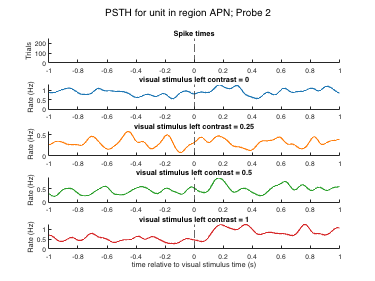

align_to = "visual_stimulus_time";
group_by = "visual_stimulus_left_contrast";
 
make_psth(...
   nwb_file, ...
   unit_id = unit_info(unit).original_id, ...
   unit_info = unit_info(unit), ...
   align_to = align_to, ...
   group_by = group_by, ...
   before_time = -1, ...
   after_time = 1, ...
   n_bins = 50, ...
   psth_plot_option = 'gaussian', ...
   std = 0.03);